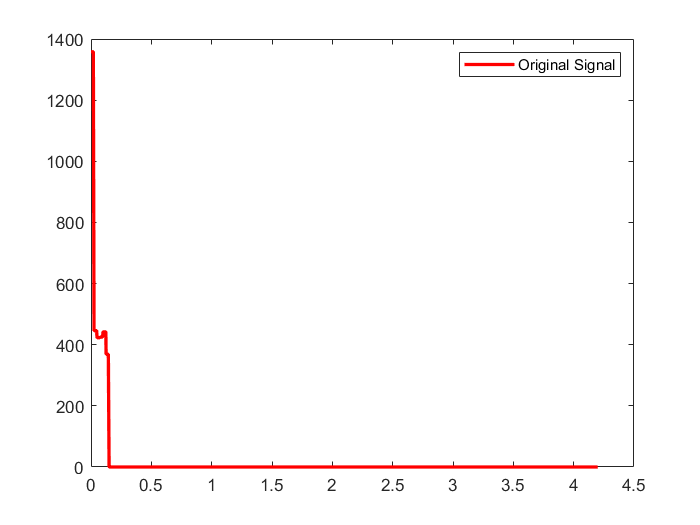

[Output,samplFreq] = audioread('birds.wav');
Output = Output(:,1);

win = 0.050;
step = 0.050;
signal = Output;
fs = samplFreq;
Len = length(Output);

Features = extractor(signal, fs, win, step);
% Feature1 = zero crossing rate
% Feature2 = Energy 
% Feature3 = SpectralCentroid
% Feature4 = Entropy
% Feature5 = SpectralFlux
% Feature6 = SpectralRolloff

plotwhichfeatures(Features,'Zero Crossing Rate',fs,Len,Output)


totalnumberoffeatures = size(Features,1);

FF = zeros(totalnumberoffeatures,1);

FF(1) = stats(Features(1,:),'mean');
FF(2) = stats(Features(2,:),'mean');
FF(3) = stats(Features(3,:),'STD');
FF(4) = stats(Features(4,:),'STD');
FF(5) = stats(Features(5,:),'STD');
FF(6) = stats(Features(6,:),'STD');

